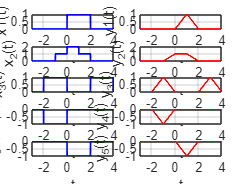

%Ex1
clear variables

figure
u=@(t)(t>=0);
x1=@(u,t)(u(t)-u(t-2));t=-3:0.01:4; subplot 521; plot(t,x1(u,t),'b','LineWidth',1);axis([-3 4 0 1]); grid; xlabel('t'); ylabel('x1(t)');
y1=@(u,t)(t.*(u(t)-u(t-1))+(u(t-1)-u(t-2)).*(2-t));subplot 522; plot(t,y1(u,t),'r','LineWidth',1);axis([-3 4 0 1]); grid;xlabel('t'); ylabel('y1(t)');
x2=x1(u,t+1)+x1(u,t); subplot 523; plot(t,x2,'b','LineWidth',1); axis([-3 4 0 2.1]); grid; xlabel('t'); ylabel('x_2(t)');
y2=y1(u,t+1)+y1(u,t); subplot 524; plot(t,y2,'r','LineWidth',1); axis([-3 4 0 2.1]); grid; xlabel('t'); ylabel('y_2(t)');
x3=x1(u,t-2)+x1(u,t+2);subplot 525; plot(t,x3,'b','LineWidth',1); axis([-3 4 0 1]); grid; xlabel('t'); ylabel('x_3(t)');
y3=y1(u,t-2)+y1(u,t+2); subplot 526; plot(t,y3,'r','LineWidth',1); axis([-3 4 0 1]); grid; xlabel('t'); ylabel('y_3(t)');
x4=-x1(u,t+2); subplot 527; plot(t,x4,'b','LineWidth',1); axis([-3 4 -1 0]); grid; xlabel('t'); ylabel('x_4(t)');
y4=-y1(u,t+2); subplot 528; plot(t,y4,'r','LineWidth',1); axis([-3 4 -1 0]); grid; xlabel('t'); ylabel('y_4(t)');
x5=-x1(u,t); subplot 529; plot(t,x5,'b','LineWidth',1); axis([-3 4 -1 0]); grid; xlabel('t'); ylabel('x_5(t)');
y5=-y1(u,t); subplot (5,2,10); plot(t,y5,'r','LineWidth',1); axis([-3 4 -1 0]); grid; xlabel('t'); ylabel('y_5(t)');

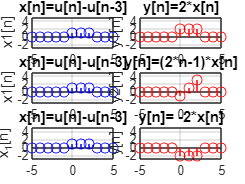


%Ex2 d)
figure
x=@(n)(u(n)-u(n-3));
n=-5:5;
subplot(3,2,1); stem(n,x(n),'b');axis([-5 5 -3 5]); grid; xlabel('n'); ylabel('x1[n]');title('x[n]=u[n]-u[n-3]');
y1=2*x(n); subplot(3,2,2); stem(n,y1,'r'); axis([-5 5 -3 5]); grid; xlabel('n'); ylabel('y1[n]');title('y[n]=2*x[n]');
subplot(3,2,3); stem(n,x(n),'b'); axis([-5 5 -3 5]); grid; xlabel('n'); ylabel('x1[n]'); title('x[n]=u[n]-u[n-3]');
y2=(2*n-1).*x(n);subplot(3,2,4);stem(n,y2,'r');axis([-5 5 -3 5]); grid;xlabel('n'); ylabel('y2[n]');title('y[n]=(2*n-1)*x[n]');
subplot(3,2,5);stem(n,x(n),'b'); axis([-5 5 -3 5]); grid; xlabel('n'); ylabel('x_1[n]'); title('x[n]=u[n]-u[n-3]');
y3=(-2+(-1).^n+(-1).^(n-1)).*x(n); subplot(3,2,6);stem(n,y3,'r'); axis([-5 5 -3 5]); grid; xlabel('n'); ylabel('y[n]'); title('y[n]= -2*x[n]');

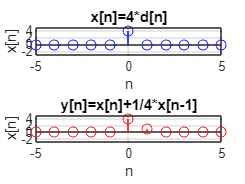


%Ex3 c)
figure
x=@(n)(4*(n==0));
y=@(n)(x(n)+(1/4)*x(n-1));
subplot(2,1,1); stem(n,x(n),'b'); axis([-5 5 -3 5]); grid; xlabel('n'); ylabel('x[n]'); title('x[n]=4*d[n]');
subplot(2,1,2); stem(n,y(n),'r'); axis([-5 5 -3 5]); grid; xlabel('n'); ylabel('x[n]'); title('y[n]=x[n]+1/4*x[n-1]');